clear
load data2.mat
n=length(data.CzasLokalnyUTC0000)

n = 516459


T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);

h10th=10*60*60*fs;
h15th=15*60*60*fs;
t=T*(h10th:h15th);
X=X';
X=X(:,h10th:h15th);
size(X)

ans =            8        3601


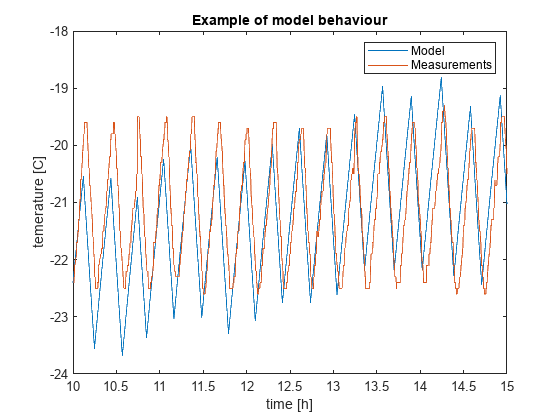

n=length(t);
X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,0;-5,0];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

x=X(2,:);
y=X_filtered(3,:);
Ta=X_filtered(1,:);

R=-99;
C=-98;
G=-1.07;
x0=y(1);
y1=ModelFunction(-x',Ta',G,R,C,t,x0);

plot(t/(60*60),y1,'-'); hold on
plot(t/(60*60),y,'-');hold off
title('Example of model behaviour')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Model','Measurements')

In spectralAnalisys:

we check spectral frequency to get freq and phase features

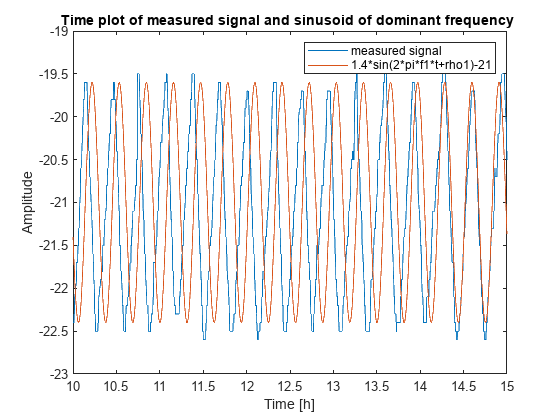

magaxis = 0:fs/length(y):fs-fs/length(y);
Y=fft(y);
mag=abs(Y);
ph=angle(Y);
[~, idx] = max(mag(2:floor(n/2)+1));
idx=idx+1;
f1=magaxis(idx);
phase1 = ph(idx);
rho1=phase1;
x=1.4*sin(2*pi*f1*t+rho1)-21;
figure
plot(t/(60*60),y);hold on
plot(t/(60*60),x);hold off
title('Time plot of measured signal and sinusoid of dominant frequency ')
legend('measured signal','1.4*sin(2*pi*f1*t+rho1)-21')
xlabel('Time [h]')
ylabel('Amplitude')

Did not work well. We now try to use the peak detection from feature extraction section and use the distance in time from model peaks to signal peaks

Ilustration:

We have to filter y to properly detect peaks:

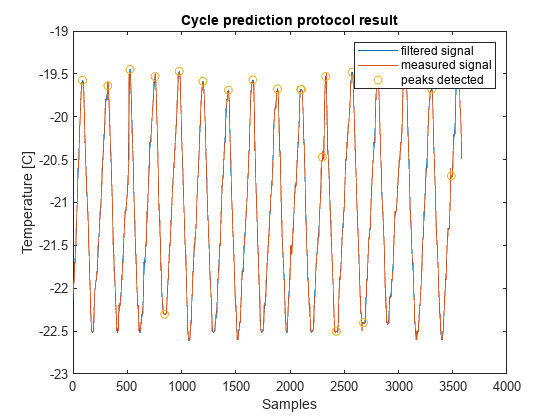

figure
y_filtered = lowpass(y,0.01);
plot(y_filtered(20:end-20));hold on;plot(y(20:end));
[pks,locs] = findpeaks(y_filtered);
y_filtered=y_filtered(20:end-20);
plot((locs)-20,pks,"o");hold off;
title('Cycle prediction protocol result')
legend('filtered signal','measured signal','peaks detected')
xlabel('Samples')
ylabel('Temperature [C]')

n=length(y_filtered);

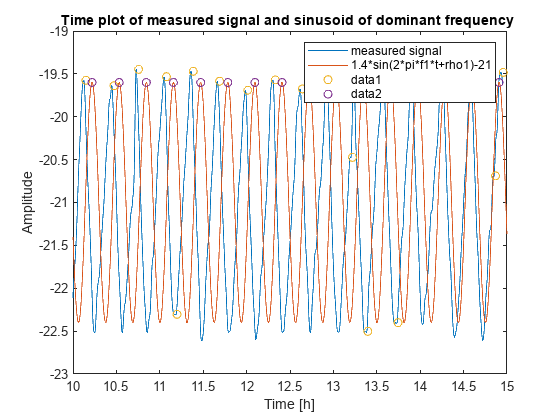

figure
plot(t(1:n)/(60*60),y_filtered);hold on
plot(t/(60*60),x);
title('Time plot of measured signal and sinusoid of dominant frequency ')
legend('measured signal','1.4*sin(2*pi*f1*t+rho1)-21')
xlabel('Time [h]')
ylabel('Amplitude')

[pks2,locs2] = findpeaks(x);
plot(t(locs)/(60*60),pks,"o")
plot(t(locs2)/(60*60),pks2,"o");hold off

Let's try on measured data vs model response

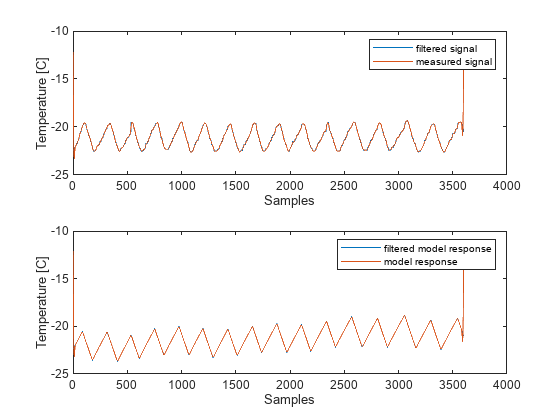

% measurements y, model response y1
% filtered y and filtered x

y_filtered = lowpass(y,0.01);
y1_filtered = lowpass(y1,0.01);
figure
subplot(211)
plot(y);hold on;
plot(y_filtered);hold off
xlabel('Samples')
ylabel('Temperature [C]')
legend('filtered signal','measured signal')
subplot(212)
plot(y1);hold on;
plot(y1_filtered);hold off
xlabel('Samples')
ylabel('Temperature [C]')
legend('filtered model response','model response')

Here we have some problems here:

1) The distortion at the begining and end of the signal are because the flter treats the signal as indefineatly periodic.

This distortion length is usualy proportional to (somwhere around) the filter order, in this case/application the filter order in between 20 and 30

2) The filter introduces phase shift, usually also proportional to the filter order

The main problem is that this implemantation in not robust, the changes will vary in different situations and the distrotion/phase shift istroduce additional points of error in our system

Imagine we had to remoove samples at the begining and end, and then, phase shift the signal. In a automatic implementation we can hardly be sure that the performance of our model is true/correct given how its assesment is influenced by the changes introduced by the filter.

In this context the simple technique of root mean square error provides real robustness while still being a good/relevant performance metric.

function dataFiltered = FilterDataL(data)

[n,m]=size(data);

%Forcing row vectros
if n>m
    data=data';
    n=temp;
    n=m;
    m=temp;
end

%Init Filter
Hd=filterData2;

%Filtering and scaling all signals one by one
for i=1:n
    
%Applying filter
x=Hd.filter(data(i,:));
x=x(30:end-30);
%Scaling the filtered signal 
group_delay = floor((length(Hd.Numerator) - 1)/2);
x = x(group_delay+1:end);

scale_factor = max(data(i,:)) / max(x);
x = x * scale_factor;

%Appending Filtered and scaled signal
dataFiltered(i,:)=x;
end
end